clear all;
close all;
%data analysis
x = gen_kmeansdata(10554466);

 Student id = 10554466


rows = size(x,1);
disp('Rows: ')

Rows: 


disp(rows);

        2028



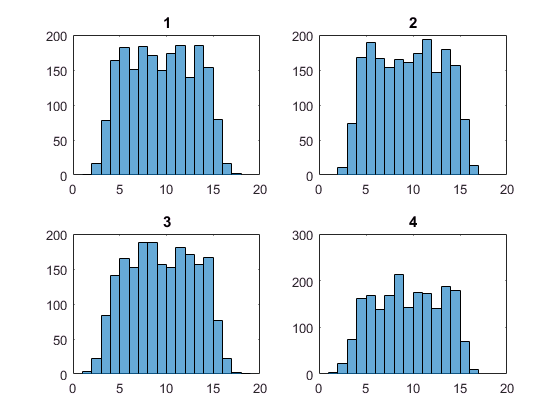

Mean of column 1 is 9.467046e+00


standard dev of column 1 is 3.532551e+00


Mean of column 2 is 9.491005e+00


standard dev of column 2 is 3.511140e+00


Mean of column 3 is 9.514930e+00


standard dev of column 3 is 3.560468e+00


Mean of column 4 is 9.496788e+00


standard dev of column 4 is 3.532174e+00



columns = size(x,2);
figure();
for c = 1:columns
    temp = x(:,c);
    M = mean(temp);
    fprintf('Mean of column %d is %d\n',c,M);
    sd = std(temp);
    fprintf('standard dev of column %d is %d\n',c,sd);
    subplot(2,2,c);
    histogram(temp);
    title(c);
end


covarianceMatrix = cov(x);
fprintf('Covariance matrix is ')

Covariance matrix is 

disp(covarianceMatrix);

   12.4789   11.3809   11.4285   11.3998
   11.3809   12.3281   11.2993   11.3381
   11.4285   11.2993   12.6769   11.4234
   11.3998   11.3381   11.4234   12.4763



correlationMatrix = corrcov(covarianceMatrix);
fprintf('Correlation matrix is ')

Correlation matrix is 

disp(correlationMatrix);

    1.0000    0.9176    0.9086    0.9136
    0.9176    1.0000    0.9039    0.9142
    0.9086    0.9039    1.0000    0.9083
    0.9136    0.9142    0.9083    1.0000



co-ordinates of centroids for k = 3 are


    9.7585    9.8132    9.7884    9.7910
   13.8104   13.7975   13.8639   13.8161
    5.5075    5.5252    5.5723    5.5538



mean silhouette for k = 3 is 6.559021e-01


co-ordinates of centroids for k = 4 are


    7.9145    7.9195    8.0114    8.0365
   13.9926   13.9677   14.0073   13.9914
    4.9724    5.0415    4.9748    4.9239
   10.9234   10.9696   11.0012   10.9712



mean silhouette for k = 4 is 7.267338e-01


co-ordinates of centroids for k = 5 are


    4.9708    5.0392    4.9718    4.9191
   14.3017   14.4530   14.6446   14.2328
   10.8931   10.9463   10.9851   10.9435
    7.9103    7.9162    8.0083    8.0351
   13.5598   13.3058   13.1431   13.6380



mean silhouette for k = 5 is 6.001589e-01


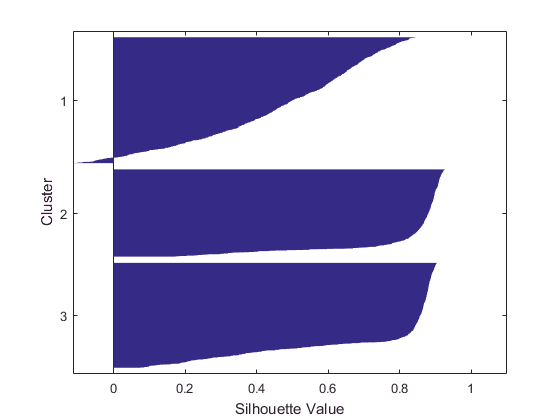

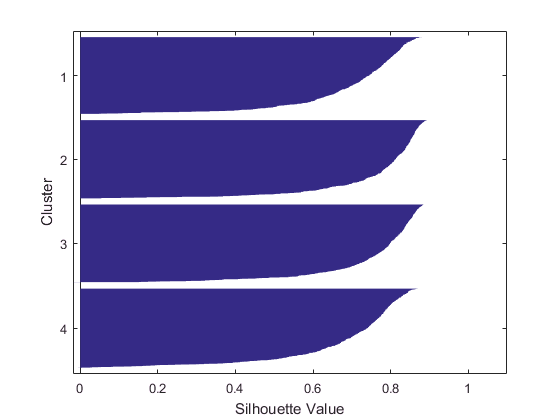

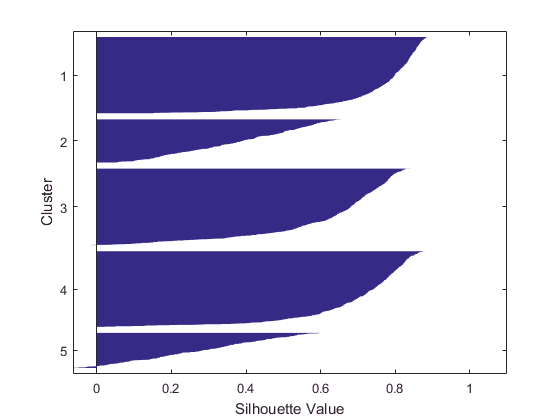


%kmeans stuff
bestsil = 0;
 for k = 3:5
     figure();
     [idx,C] = kmeans(x,k);
     fprintf('co-ordinates of centroids for k = %d are\n',k)
     disp(C);
     silhouette(x,idx);
     meansil = mean(silhouette(x,idx)); 
     if meansil > bestsil
         bestsil = meansil;
         bestk = k;
         bestidx = idx;
         bestC = C;
     end
     fprintf('mean silhouette for k = %d is %d\n',k,meansil);
 end;

 fprintf('best clustering is %d\n', bestk);

best clustering is 4


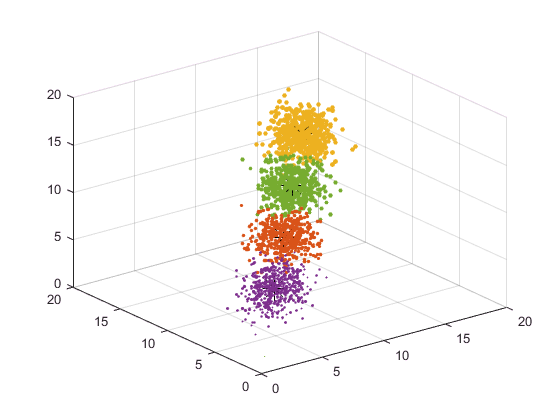

 %scatter best clustering
 figure();
 scatter3(bestC(:,1),bestC(:,2),bestC(:,3),200,'black','*');
 hold on;
 for j = 1:bestk;
     tempScat = ones(1,4);
     for i = 1:size(bestidx);
         if bestidx(i) == j
             tempScat = cat(1,tempScat,x(i,:));
         end
     end;
     scatter3(tempScat(:,1),tempScat(:,2),tempScat(:,3),tempScat(:,4),'filled');
 end;